**Key Parameters to Align with Zombie Movie Data**

**Zombie Destruction Rate (**`a`**)**:

- In films, this would depend on how effective humans are at destroying zombies. For example:

- In *World War Z*, fast-moving zombies and large hordes suggest a **low** `a`.

- In *Shaun of the Dead*, smaller groups of zombies and comedic inefficiency might still allow for higher destruction rates.

**New Zombie Rate (**`b`**)**:

- This is the rate at which humans are turned into zombies. High in movies like *28 Days Later* (rapid infection), but lower in scenarios like *The Walking Dead* where bites take time to transform victims.

**Resurrection Rate (**`ze`**)**:

- In most films, dead humans return as zombies after a period. This rate varies:

- Near-zero in *28 Days Later* (no true resurrection, just infection).

- Higher in *Night of the Living Dead*, where even buried corpses can rise.

**Background Death Rate (**`d`**)**:

- Reflects natural human death unrelated to the outbreak. Generally low in most films.

**Kill Rate (**`k`**)**:

- Reflects the success of eradication campaigns. In movies like *World War Z*, massive military operations suggest a **high **`k`, while small groups like in *The Walking Dead* imply a **low **`k`.

**Impulse Timing (**`Ti`**)**:

- Determines how frequently humans launch counterattacks. For instance:

- Frequent, large-scale attacks in *World War Z* (short `Ti`).

- Irregular and reactive attacks in *The Walking Dead* (long `Ti`).

%Math Modeling, Zombie Outbreak
clear all; close all; clc;

## SIZR Model with treatment

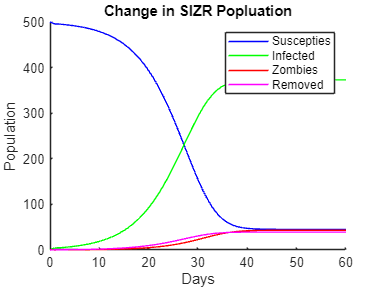

clear all; close all; clc;

syms S %Population of susceptible people
syms I %Population of infected people
syms Z %Population of zombies
syms R %Population of removed people and zombies

syms Sstar
syms Istar
syms Zstar
syms Rstar

syms delta %Non zombie related deaths
syms zeta %Resurrected humans that turn into zombies
syms beta %Zombie encounter transmission parameter
syms m %Birth rate (constant)
syms alpha %Defeated zombie parameter
syms rho %Infectious period parameter
syms N %Total population
syms c %Cure parameter

alphaN = 0.001; %0.005
betaN = 0.0095; %0.0095
deltaN = 0.001; %0.0001
zetaN = 0.05; %0.0001
rhoN = 0.05;
Npop = 500;
cN = 0.43; %Test 0.1, 0.3, 0,5

%Set up ODE
T = 60; %Total number of days
dt = 1; %Change in unit time (one day)
n = T/dt;
t = zeros(1,n+1);
s = zeros(1,n+1);
i = zeros(1,n+1);
z = zeros(1,n+1);
r = zeros(1,n+1);
t = 0:dt:T;

%Assume: Short period of time
m = 0;
delta = 0;

%ODE
Sprime = m - (beta*S*Z) - (delta*S) + (c*Z);
Iprime = (beta*S*Z) - (rho*I) - (delta*I);
Zprime = (rho*I) + (zeta*R) - (alpha*S*Z) - (c*Z);
Rprime = (delta*S) + (delta*I) + (alpha*S*Z) - (zeta*R);

J = jacobian([Sprime, Iprime, Zprime, Rprime], [S,I,Z,R]); %Initial jacobian matrix
J1 = subs(J, [S,I,Z,R] , [N,0,0,0]); %Jacobian matrix of first steady state
J2 = subs(J, [S,I,Z,R] , [0,0,Zstar,0]); %Jacobian matrix of second steady state

%Identity matrix
syms lambda
I = [lambda,0,0,0; 0,lambda,0,0; 0,0,lambda,0; 0,0,0,lambda];
J1 = J1-I;
J2 = J2-I;

%Determinant of (J-lambdaI)
dJ1 = det(J1);
dJ2 = det(J2);

dJ1 = vpa(subs(dJ1, [alpha, beta, zeta, rho, c, N], [alphaN, betaN, zetaN, rhoN, cN, Npop]),3);
dJ2 = vpa(subs(dJ2, [alpha, beta, zeta, N, rho, c, Zstar], [alphaN, betaN, zetaN, rhoN, cN, Npop, 1]),3);

%Solve for roots of polynomial equation
L1 = vpa(solve(dJ1),3);
L2 = vpa(solve(dJ2),3);

%Switch back to numerical values to solve ODE and graph
s(1) = Npop;
i(1) = 0;
z(1) = 1;
r(1) = 0;

for x = 1:n
    s(x+1) = s(x) + dt*(-betaN*s(x)*z(x) + cN*z(x));
    i(x+1) = i(x) + dt*(betaN*s(x)*z(x) - rhoN*i(x));
    z(x+1) = z(x) + dt*(rhoN*i(x) + zetaN*r(x) - alphaN*s(x)*z(x) - cN*z(x));
    r(x+1) = r(x) + dt*(alphaN*s(x)*z(x) - zetaN*r(x));
    
    %Assume: S, I, Z, and R > 0 and S, I, Z, and R < N
    if s(x+1) < 0
        s(x+1) = 0;
    end
    if s(x+1) > Npop
        s(x+1) = Npop;
    end
    
    if i(x+1) < 0
        i(x+1) = 0;
    end
    if i(x+1) > Npop
        i(x+1) = Npop;
    end
    
    if z(x+1) < 0
        z(x+1) = 0;
    end
    if z(x+1) > Npop
        z(x+1) = Npop;
    end
    
    if r(x+1) < 0
        r(x+1) = 0;
    end
    if r(x+1) > Npop
        r(x+1) = Npop;
    end
end

hold on
plot(t,s,'b');
plot(t,i,'g');
plot(t,z,'r');
plot(t,r,'m');
xlabel('Days');
ylabel('Population');
legend('Suscepties','Infected','Zombies','Removed')
title('Change in SIZR Popluation');
axis([0, T, 0, Npop])

## SIZRQ Model

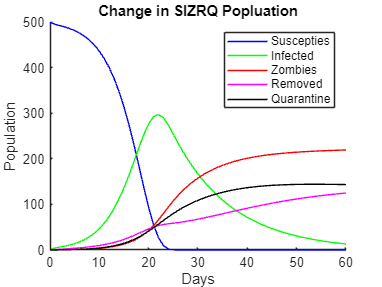

clear all; close all; clc;

alphaN = 0.001; %0.005
betaN = 0.0095; %0.0095
deltaN = 0.001; %0.0001
zetaN = 0.05; %0.0001
rhoN = 0.05;
Npop = 500;
sigmaN = 0.03; %Zombie population entering quarantine
kN = 0.03; %Infected popluation entering quarantine
gammaN = 0.05; %Quarantine popluation being removed


%Set up ODE
T = 60; %Total number of days
dt = 1; %Change in unit time (one day)
n = T/dt;
t = zeros(1,n+1);
s = zeros(1,n+1);
i = zeros(1,n+1);
z = zeros(1,n+1);
r = zeros(1,n+1);
q = zeros(1,n+1);
t = 0:dt:T;

%Switch back to numerical values to solve ODE and graph
s(1) = Npop;
i(1) = 0;
z(1) = 1;
r(1) = 0;
q(1) = 0;

for x = 1:n
    s(x+1) = s(x) + dt*(-betaN*s(x)*z(x) - deltaN*s(x));
    i(x+1) = i(x) + dt*(betaN*s(x)*z(x) - rhoN*i(x) - deltaN*i(x) - kN*i(x));
    z(x+1) = z(x) + dt*(rhoN*i(x) + zetaN*r(x) - alphaN*s(x)*z(x) - sigmaN*z(x));
    r(x+1) = r(x) + dt*(deltaN*s(x) + deltaN*i(x) + alphaN*s(x)*z(x) - zetaN*r(x) + gammaN*q(x));
    q(x+1) = q(x) + dt*(kN*i(x) + sigmaN*z(x) - gammaN*q(x));
    
    %Assume: S, I, Z, R, Q > 0 and S, I, Z, R, Q < N
    if s(x+1) < 0
        s(x+1) = 0;
    end
    if s(x+1) > Npop
        s(x+1) = Npop;
    end
    
    if i(x+1) < 0
        i(x+1) = 0;
    end
    if i(x+1) > Npop
        i(x+1) = Npop;
    end
    
    if z(x+1) < 0
        z(x+1) = 0;
    end
    if z(x+1) > Npop
        z(x+1) = Npop;
    end
    
    if r(x+1) < 0
        r(x+1) = 0;
    end
    if r(x+1) > Npop
        r(x+1) = Npop;
    end
    
    if q(x+1) < 0
        q(x+1) = 0;
    end
    if q(x+1) > Npop
        q(x+1) = Npop;
    end
end

hold on
plot(t,s,'b');
plot(t,i,'g');
plot(t,z,'r');
plot(t,r,'m');
plot(t,q,'k');
xlabel('Days');
ylabel('Population');
legend('Suscepties','Infected','Zombies','Removed','Quarantine')
title('Change in SIZRQ Popluation');
axis([0, T, 0, Npop])

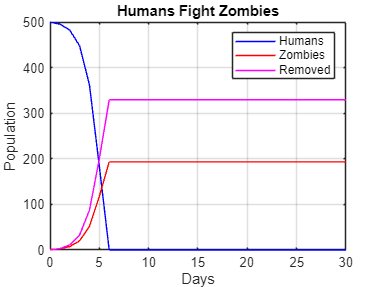

% Human fights zombies

clear; clc;

% Parameters
alpha = 0.001;      % Defeated zombie parameter
beta = 0.0095;      % Zombie encounter transmission
fight_rate = 0.005; % Rate at which humans defeat zombies
Npop = 500;         % Total population
T = 30;             % Total days
dt = 1;             % Time step
t = 0:dt:T;         % Time array

% Initial Conditions
s = zeros(size(t));
z = zeros(size(t));
r = zeros(size(t));
s(1) = Npop;
z(1) = 1;
r(1) = 0;

% Simulation Loop
for k = 1:length(t)-1
    ds = -beta * s(k) * z(k);
    dz = beta * s(k) * z(k) - alpha * s(k) * z(k) - fight_rate * s(k) * z(k);
    dr = alpha * s(k) * z(k) + fight_rate * s(k) * z(k);
    
    s(k+1) = max(0, s(k) + dt * ds);
    z(k+1) = max(0, z(k) + dt * dz);
    r(k+1) = max(0, r(k) + dt * dr);
end

% Plot Results
figure;
plot(t, s, 'b', t, z, 'r', t, r, 'm');
xlabel('Days');
ylabel('Population');
legend('Humans', 'Zombies', 'Removed');
title('Humans Fight Zombies');
grid on;

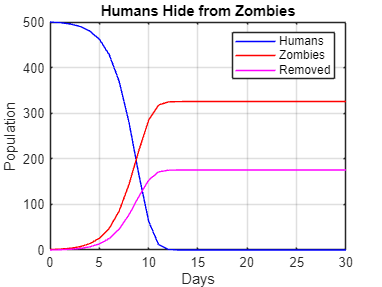

clear; clc;

% Parameters
alpha = 0.001;      % Defeated zombie parameter
beta = 0.0095;      % Zombie encounter transmission
hide_rate = 0.7;    % Proportion of humans hiding
Npop = 500;         % Total population
T = 30;             % Total days
dt = 1;             % Time step
t = 0:dt:T;         % Time array

% Initial Conditions
s = zeros(size(t));
z = zeros(size(t));
r = zeros(size(t));
s(1) = Npop;
z(1) = 1;
r(1) = 0;

% Simulation Loop
for k = 1:length(t)-1
    effective_beta = beta * (1 - hide_rate); % Reduced transmission due to hiding
    ds = -effective_beta * s(k) * z(k);
    dz = effective_beta * s(k) * z(k) - alpha * s(k) * z(k);
    dr = alpha * s(k) * z(k);
    
    s(k+1) = max(0, s(k) + dt * ds);
    z(k+1) = max(0, z(k) + dt * dz);
    r(k+1) = max(0, r(k) + dt * dr);
end

% Plot Results
figure;
plot(t, s, 'b', t, z, 'r', t, r, 'm');
xlabel('Days');
ylabel('Population');
legend('Humans', 'Zombies', 'Removed');
title('Humans Hide from Zombies');
grid on;

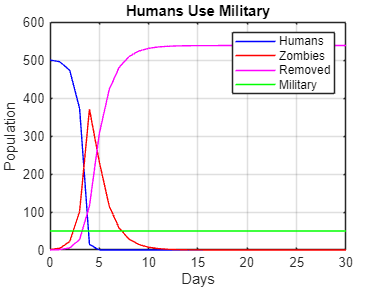

clear; clc;

% Parameters
alpha = 0.001;        % Defeated zombie parameter
beta = 0.0095;        % Zombie encounter transmission
military_rate = 0.01; % Military efficiency in defeating zombies
Npop = 500;           % Total population
military = 50;        % Initial number of soldiers
T = 30;               % Total days
dt = 1;               % Time step
t = 0:dt:T;           % Time array

% Initial Conditions
s = zeros(size(t));
z = zeros(size(t));
r = zeros(size(t));
m = zeros(size(t)); % Military population
s(1) = Npop;
z(1) = 1;
r(1) = 0;
m(1) = military;

% Simulation Loop
for k = 1:length(t)-1
    ds = -beta * s(k) * z(k);
    dz = beta * s(k) * z(k) - alpha * s(k) * z(k) - military_rate * m(k) * z(k);
    dr = alpha * s(k) * z(k) + military_rate * m(k) * z(k);
    
    s(k+1) = max(0, s(k) + dt * ds);
    z(k+1) = max(0, z(k) + dt * dz);
    r(k+1) = max(0, r(k) + dt * dr);
    m(k+1) = m(k); % Assuming military size remains constant
end

% Plot Results
figure;
plot(t, s, 'b', t, z, 'r', t, r, 'm', t, m, 'g');
xlabel('Days');
ylabel('Population');
legend('Humans', 'Zombies', 'Removed', 'Military');
title('Humans Use Military');
grid on;

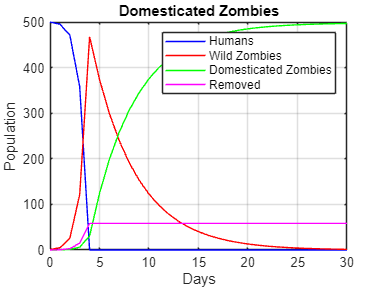

clear; clc;

% Parameters
alpha = 0.001;        % Defeated zombie parameter
beta = 0.0095;        % Zombie encounter transmission
dom_rate = 0.2;     % Domestication rate of zombies
Npop = 500;           % Total population
T = 30;               % Total days
dt = 1;               % Time step
t = 0:dt:T;           % Time array

% Initial Conditions
s = zeros(size(t));
wild_z = zeros(size(t));
dom_z = zeros(size(t));
r = zeros(size(t));
s(1) = Npop;
wild_z(1) = 1;
dom_z(1) = 0;
r(1) = 0;

% Simulation Loop
for k = 1:length(t)-1
    ds = -beta * s(k) * wild_z(k);
    dwild_z = beta * s(k) * wild_z(k) - alpha * s(k) * wild_z(k) - dom_rate * wild_z(k);
    ddom_z = dom_rate * wild_z(k);
    dr = alpha * s(k) * wild_z(k);
    
    s(k+1) = max(0, s(k) + dt * ds);
    wild_z(k+1) = max(0, wild_z(k) + dt * dwild_z);
    dom_z(k+1) = max(0, dom_z(k) + dt * ddom_z);
    r(k+1) = max(0, r(k) + dt * dr);
end

% Plot Results
figure;
plot(t, s, 'b', t, wild_z, 'r', t, dom_z, 'g', t, r, 'm');
xlabel('Days');
ylabel('Population');
legend('Humans', 'Wild Zombies', 'Domesticated Zombies', 'Removed');
title('Domesticated Zombies');
grid on;

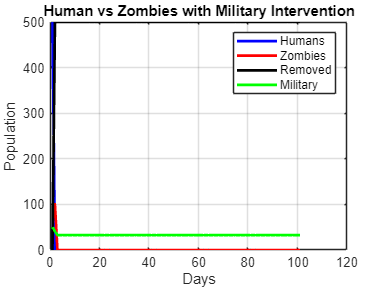

clc; clear;
% Parameters
total_time = 100; % Simulation time
s(1) = 500;       % Initial human population
z(1) = 100;       % Initial zombie population
r(1) = 0;         % Initial removed (dead) population
m(1) = 50;        % Initial military population
fight_rate = 0.01;  % Humans fighting zombies
mil_eff = 0.05;     % Military efficiency in reducing zombies
casualty_rate = 0.002; % Rate of military casualties
recruit_rate = 0.002; % Recruitment rate of soldiers from human population

% Simulation
for k = 1:total_time
    % Humans fighting zombies
    s(k+1) = s(k) - fight_rate * s(k) * z(k);
    % Zombies killed by humans and military
    z(k+1) = z(k) + (0.005 * z(k) * s(k)) - mil_eff * m(k) * z(k);
    % Removed humans
    r(k+1) = r(k) + fight_rate * s(k) * z(k);
    % Military dynamics
    m(k+1) = m(k) + recruit_rate * s(k) - casualty_rate * z(k) * m(k);
    
    % Ensure populations are non-negative
    s(k+1) = max(s(k+1), 0);
    z(k+1) = max(z(k+1), 0);
    r(k+1) = max(r(k+1), 0);
    m(k+1) = max(m(k+1), 0);
end

% Plot results
time = 1:total_time + 1;
figure;
plot(time, s, 'b', 'LineWidth', 2); hold on;
plot(time, z, 'r', 'LineWidth', 2);
plot(time, r, 'k', 'LineWidth', 2);
plot(time, m, 'g', 'LineWidth', 2);
xlabel('Days');
ylabel('Population');
legend('Humans', 'Zombies', 'Removed', 'Military');
title('Human vs Zombies with Military Intervention');
grid on;

## SZR Model

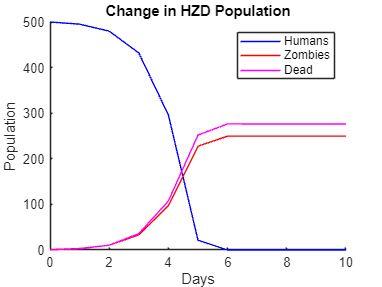

clear all; close all; clc;

% Define symbolic variables
syms H % Population of humans
syms Z % Population of zombies
syms D % Population of dead (removed humans and zombies)

syms delta % Non-zombie-related deaths
syms zeta % Resurrected humans that turn into zombies
syms beta % Zombie encounter transmission parameter
syms m % Birth rate (constant)
syms alpha % Defeated zombie parameter
syms N % Total population

% Numerical values, "N" denotes numerical variables instead of symbolic variable
alphaN = 0.005; % Test 0.002, 0.008
betaN = 0.0095; % Test 0.0065, 0.0125
deltaN = 0.0001;
zetaN = 0.0001;
Npop = 500;

% Set up ODE
T = 10; % Total number of days
dt = 1; % Change in unit time (one day)
n = T/dt;
t = zeros(1, n+1);
h = zeros(1, n+1); % Human population
z = zeros(1, n+1); % Zombie population
d = zeros(1, n+1); % Dead population
t = 0:dt:T;

% Assume: Short period of time
m = 0;
delta = 0;

% ODE
Hprime = m - (beta * H * Z) - (delta * H);
Zprime = (beta * H * Z) + (zeta * D) - (alpha * H * Z);
Dprime = (delta * H) + (alpha * H * Z) - (zeta * D);

J = jacobian([Hprime, Zprime, Dprime], [H, Z, D]); % Initial Jacobian matrix
J1 = subs(J, [H, Z, D], [N, 0, 0]); % Jacobian matrix of first steady state
J2 = subs(J, [H, Z, D], [0, Z, 0]); % Jacobian matrix of second steady state

% Identity matrix
syms lambda
I = [lambda, 0, 0; 0, lambda, 0; 0, 0, lambda];
J1 = J1 - I;
J2 = J2 - I;

% Determinant of (J - lambda*I)
dJ1 = det(J1);
dJ2 = det(J2);

dJ1 = vpa(subs(dJ1, [alpha, beta, zeta, N], [alphaN, betaN, zetaN, Npop]), 3);
dJ2 = vpa(subs(dJ2, [alpha, beta, zeta, N, Z], [alphaN, betaN, zetaN, Npop, 1]), 3);

% Solve for roots of polynomial equation
L1 = vpa(solve(dJ1), 3);
L2 = vpa(solve(dJ2), 3);

% Switch back to numerical values to solve ODE and graph
h(1) = Npop; % Initial human population
z(1) = 1;    % Initial zombie population
d(1) = 0;    % Initial dead population

for x = 1:n
    h(x+1) = h(x) + dt * (-betaN * h(x) * z(x));
    z(x+1) = z(x) + dt * (betaN * h(x) * z(x) - alphaN * h(x) * z(x) + zetaN * d(x));
    d(x+1) = d(x) + dt * (alphaN * h(x) * z(x) + deltaN * h(x) - zetaN * d(x));
    
    % Assume: H, Z, and D > 0 and H, Z, and D < N
    if h(x+1) < 0
        h(x+1) = 0;
    end
    if h(x+1) > Npop
        h(x+1) = Npop;
    end
    
    if z(x+1) < 0
        z(x+1) = 0;
    end
    if z(x+1) > Npop
        z(x+1) = Npop;
    end
    
    if d(x+1) < 0
        d(x+1) = 0;
    end
    if d(x+1) > Npop
        d(x+1) = Npop;
    end
end

% Plot results
hold on
plot(t, h, 'b'); % Humans
plot(t, z, 'r'); % Zombies
plot(t, d, 'm'); % Dead
xlabel('Days');
ylabel('Population');
legend('Humans', 'Zombies', 'Dead');
title('Change in HZD Population');
axis([0, T, 0, Npop]);

## SZIR Model

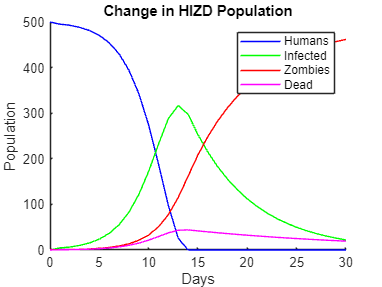

clear all; close all; clc;

% Define symbolic variables for the populations
syms H % Population of humans
syms I % Population of infected humans
syms Z % Population of zombies
syms D % Population of dead (removed humans and zombies)

syms delta % Death rate (non-zombie-related)
syms zeta % Rate at which dead humans become zombies
syms beta % Zombie transmission rate (via encounters with humans)
syms m % Birth rate of humans (assumed constant)
syms alpha % Rate of zombie elimination by humans
syms rho % Rate of infected humans turning into zombies
syms N % Total population

% Numerical parameter values
alphaN = 0.001; % Zombie elimination rate by humans
betaN = 0.0095; % Zombie transmission rate
deltaN = 0.001; % Non-zombie-related human death rate
zetaN = 0.05;   % Resurrection rate of dead humans into zombies
rhoN = 0.15;    % Infected-to-zombie transition rate
Npop = 500;     % Total initial population

% Simulation parameters
T = 30;  % Total simulation time (in days)
dt = 1;  % Time step (1 day)
n = T/dt; % Number of simulation steps
t = 0:dt:T; % Time vector for plotting

% Initialize populations
h = zeros(1, n+1); % Humans
i = zeros(1, n+1); % Infected
z = zeros(1, n+1); % Zombies
d = zeros(1, n+1); % Dead
h(1) = Npop;       % Initial human population
i(1) = 0;          % Initial infected population
z(1) = 1;          % Initial zombie population
d(1) = 0;          % Initial dead population

% Assume short period, no births or unrelated deaths
m = 0;
delta = 0;

% ODEs defining the system dynamics
Hprime = m - (beta * H * Z) - (delta * H);               % Change in humans
Iprime = (beta * H * Z) - (rho * I) - (delta * I);       % Change in infected
Zprime = (rho * I) + (zeta * D) - (alpha * H * Z);       % Change in zombies
Dprime = (delta * H) + (delta * I) + (alpha * H * Z) - (zeta * D); % Change in dead

% Jacobian matrix (linear stability analysis)
J = jacobian([Hprime, Iprime, Zprime, Dprime], [H, I, Z, D]);

% Calculate Jacobian for steady states
J1 = subs(J, [H, I, Z, D], [N, 0, 0, 0]);  % Steady state: all humans, no zombies
J2 = subs(J, [H, I, Z, D], [0, 0, Z, 0]);  % Steady state: all zombies

% Add identity matrix (for characteristic equation)
syms lambda
I = [lambda, 0, 0, 0; 0, lambda, 0, 0; 0, 0, lambda, 0; 0, 0, 0, lambda];
J1 = J1 - I;
J2 = J2 - I;

% Determinant of (J - lambda * I) for eigenvalues
dJ1 = det(J1);
dJ2 = det(J2);

% Substitute numerical values into determinant equations
dJ1 = vpa(subs(dJ1, [alpha, beta, zeta, rho, N], [alphaN, betaN, zetaN, rhoN, Npop]), 3);
dJ2 = vpa(subs(dJ2, [alpha, beta, zeta, rho, N, Z], [alphaN, betaN, zetaN, rhoN, Npop, 1]), 3);

% Solve for eigenvalues of the system
L1 = vpa(solve(dJ1), 3); % Eigenvalues for first steady state
L2 = vpa(solve(dJ2), 3); % Eigenvalues for second steady state

% Numerical integration of ODEs over time
for x = 1:n
    h(x+1) = h(x) + dt * (-betaN * h(x) * z(x) - delta * h(x));
    i(x+1) = i(x) + dt * (betaN * h(x) * z(x) - rhoN * i(x));
    z(x+1) = z(x) + dt * (rhoN * i(x) + zetaN * d(x) - alphaN * h(x) * z(x));
    d(x+1) = d(x) + dt * (alphaN * h(x) * z(x) - zetaN * d(x));
    
    % Ensure populations remain within valid bounds
    if h(x+1) < 0, h(x+1) = 0; end
    if h(x+1) > Npop, h(x+1) = Npop; end
    
    if i(x+1) < 0, i(x+1) = 0; end
    if i(x+1) > Npop, i(x+1) = Npop; end
    
    if z(x+1) < 0, z(x+1) = 0; end
    if z(x+1) > Npop, z(x+1) = Npop; end
    
    if d(x+1) < 0, d(x+1) = 0; end
    if d(x+1) > Npop, d(x+1) = Npop; end
end

% Plot results
hold on
plot(t, h, 'b'); % Plot human population
plot(t, i, 'g'); % Plot infected population
plot(t, z, 'r'); % Plot zombie population
plot(t, d, 'm'); % Plot dead population
xlabel('Days');
ylabel('Population');
legend('Humans', 'Infected', 'Zombies', 'Dead');
title('Change in HIZD Population');
axis([0, T, 0, Npop]);

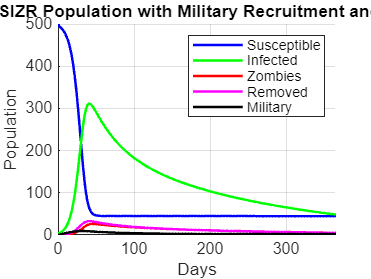

clear all; close all; clc;

syms S % Population of susceptible people
syms I % Population of infected people
syms Z % Population of zombies
syms R % Population of removed people and zombies
syms M % Population of military personnel

syms delta % Non-zombie-related deaths
syms zeta % Resurrected humans that turn into zombies
syms beta % Zombie encounter transmission parameter
syms m % Birth rate (constant)
syms alpha % Defeated zombie parameter
syms rho % Infectious period parameter
syms N % Total population
syms c % Cure parameter
syms mu % Military efficiency in reducing zombies
syms gamma % Recruitment rate for military personnel

% Parameter values
alphaN = 0.001; % Zombie elimination by civilians
betaN = 0.0095; % Zombie encounter transmission parameter
deltaN = 0.001; % Non-zombie-related deaths
zetaN = 0.05; % Resurrected humans that turn into zombies
rhoN = 0.05; % Recovery rate of infected
muN = 0.02; % Military efficiency
gammaN = 0.001; % Recruitment rate for military personnel
Npop = 500; % Total population
cN = 0.43; % Cure efficiency

% Time settings
T = 365; % Total number of days
dt = 1; % Change in unit time (one day)
n = T/dt; % Number of time steps
t = 0:dt:T;

% Initial population values
s = zeros(1, n+1);
i = zeros(1, n+1);
z = zeros(1, n+1);
r = zeros(1, n+1);
m = zeros(1, n+1); % Military population
s(1) = Npop;
i(1) = 0;
z(1) = 1;
r(1) = 0;
m(1) = 0;

% ODEs with military recruitment and intervention
for x = 1:n
    s(x+1) = s(x) + dt * (-betaN * s(x) * z(x) + cN * z(x) - gammaN * s(x));
    i(x+1) = i(x) + dt * (betaN * s(x) * z(x) - rhoN * i(x));
    z(x+1) = z(x) + dt * (rhoN * i(x) + zetaN * r(x) - alphaN * s(x) * z(x) - cN * z(x) - muN * m(x) * z(x));
    r(x+1) = r(x) + dt * (alphaN * s(x) * z(x) - zetaN * r(x));
    m(x+1) = m(x) + dt * (gammaN * s(x) - muN * m(x));
    
    % Ensure populations stay within realistic bounds
    s(x+1) = max(0, min(Npop, s(x+1)));
    i(x+1) = max(0, min(Npop, i(x+1)));
    z(x+1) = max(0, min(Npop, z(x+1)));
    r(x+1) = max(0, min(Npop, r(x+1)));
    m(x+1) = max(0, min(Npop, m(x+1)));
end

% Plotting the results
figure;
hold on;
plot(t, s, 'b', 'LineWidth', 1.5);
plot(t, i, 'g', 'LineWidth', 1.5);
plot(t, z, 'r', 'LineWidth', 1.5);
plot(t, r, 'm', 'LineWidth', 1.5);
plot(t, m, 'k', 'LineWidth', 1.5); % Military population
xlabel('Days');
ylabel('Population');
legend('Susceptible', 'Infected', 'Zombies', 'Removed', 'Military');
title('Change in SIZR Population with Military Recruitment and Intervention');
axis([0, T, 0, Npop]);
grid on;